# SLCO4A - Aula Prática 14

## Sistema de controle simples

**Exercício 1: **Considere um sistema de controle automático de posição, o qual pode ser utilizado para controlar a posição angular de um objeto pesado (por exemplo uma antena de rastreamento, uma posição de uma nave, um painel solar, uma janela ou qualquer outro mecanismo) especificado pela seguinte função de transferência:

 
$$H\left(s\right)=\frac{1}{s\left(s+8\right)}$$


a) Avalie a estabilidade do sistema.

num = 1;
den = conv([1 0], [1 8]);
H = tf(num,den);
roots(den)

ans =      0
    -8


%Sistema criticamente estável
%step(H)


b) Determine a resposta temporal de saída do sistema com ganho $K=7$, $K=16$ e $K=80$ operando em malha fechada para uma entrada degrau unitário.

K = 7;
%Função de malha fechada
figure
T1 = feedback(K*H, 1)

T1 =
 
        7
  -------------
  s^2 + 8 s + 7
 
Continuous-time transfer function.



step(T1, 'b')
hold on
K = 16;
%Função de malha fechada
T2 = feedback(K*H, 1)

T2 =
 
        16
  --------------
  s^2 + 8 s + 16
 
Continuous-time transfer function.



step(T2, 'r')
K = 80;
%Função de malha fechada
T3 = feedback(K*H, 1)

T3 =
 
        80
  --------------
  s^2 + 8 s + 80
 
Continuous-time transfer function.



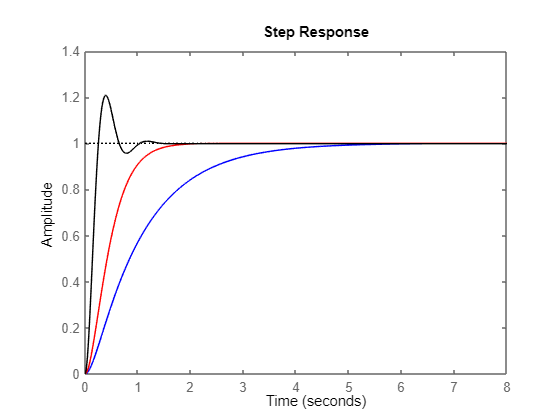

step(T3, 'k')

c) Determine a resposta temporal de saída do sistema operando em malha fechada com ganho proporcional $K=80$ para uma entrada do tipo rampa.

T4 = series(tf([0 1], [1 0]), T3);

T4 =
 
          80
  ------------------
  s^3 + 8 s^2 + 80 s
 
Continuous-time transfer function.



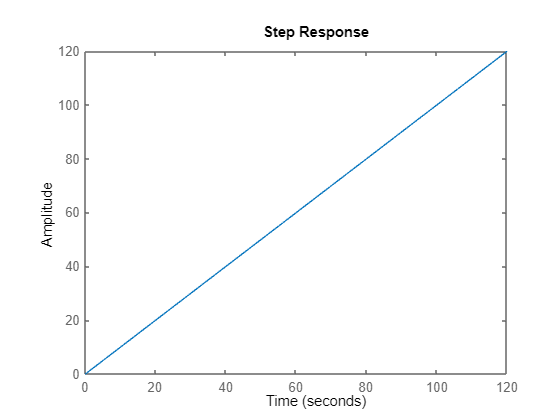

figure 
step(T4)

## Resposta em frequência

Um sistema é completamente especificado por sua resposta impulsiva. Consequentemente, pode-se determinar a saída $y\left(t\right)$como sendo


$$y\left(t\right)=h\left(t\right)*x\left(t\right)$$


Aplicando transformada de Fourier, obtém-se


$$Y\left(j\omega \right)=H\left(j\omega \;\right)X\left(j\omega \right)$$


- $H\left(j\omega \;\right)$é chamada de resposta em frequência, que corresponde a transformada de Fourier da resposta impulsiva $h\left(t\right)$do sistema.

- $H\left(j\omega \;\right)$usualmente é uma função de valor complexo, logo pode ser denotada na forma polar

$H\left(j\omega \right)=\left|H\left(j\omega \right)\right|e^{j\angle \;H\left(j\omega \right)}$, 

onde $\left|H\left(j\omega \right)\right|$ é a magnitude e $e^{j\angle \;H\left(j\omega \right)}$ é a fase de $H\left(j\omega \right)$.

**Exercício 2: **Calcule a resposta de frequência $H\left(j\omega \right)$de um sistema descrito pela resposta de impulso $h\left(t\right)=e^{-2t} u\left(t\right)$. Represente graficamente a magnitude e a fase da resposta de frequência para  $0\le \omega \le 10$ rad/s, com passo de 0.1 rad/s

syms t w 
h = exp(-2*t)*heaviside(t);
H = fourier(h, w)

$$H = \frac{1}{2+w\,\mathrm{i}}$$

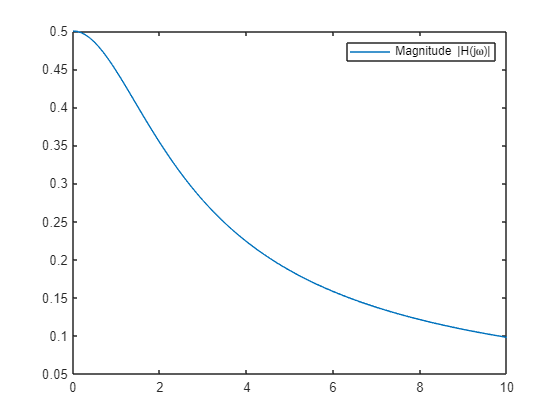

w1 = 0:0.1:10;
HH = subs(H, w, w1);
plot(w1, abs(HH))
legend('Magnitude |H(j\omega)|')

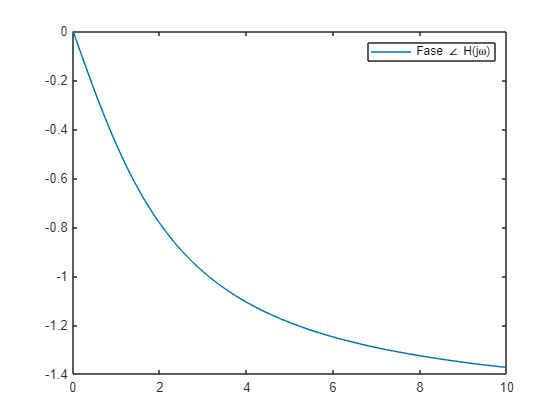

plot(w1, angle(HH))
legend('Fase \angle H(j\omega)')

### Comando freqs

**Exercício 3: **Plot a magnitude e a fase da resposta em frequência de um sistema dado por 


$$H\left(j\omega \right)=\frac{B\left(j\omega \;\right)}{A\left(j\omega \;\right)}=\frac{8{\left(j\omega \right)}^2 +2j\omega +20}{6{\left(j\omega \right)}^2 -5j\omega -10}$$


para  $0\le \omega \le 10$ rad/s, com passo de 0.1 rad/s

num = [8 2 20];
den = [6 -5 -10];
w = 0:0.1:10;
H = freqs(num, den, w);

H =   -2.0000 + 0.0000i  -1.9762 + 0.0783i  -1.9075 + 0.1472i  -1.8008 + 0.1994i  -1.6659 + 0.2310i  -1.5126 + 0.2419i  -1.3501 + 0.2344i  -1.1852 + 0.2124i  -1.0231 + 0.1801i  -0.8670 + 0.1414i  -0.7189 + 0.0996i  -0.5797 + 0.0573i  -0.4498 + 0.0160i  -0.3291 - 0.0229i  -0.2174 - 0.0587i  -0.1142 - 0.0912i  -0.0190 - 0.1202i   0.0688 - 0.1458i   0.1497 - 0.1681i   0.2243 - 0.1873i   0.2930 - 0.2038i   0.3564 - 0.2178i   0.4148 - 0.2296i   0.4688 - 0.2394i   0.5187 - 0.2474i   0.5648 - 0.2539i   0.6074 - 0.2590i   0.6470 - 0.2630i   0.6837 - 0.2660i   0.7177 - 0.2681i   0.7494 - 0.2694i   0.7788 - 0.2700i   0.8062 - 0.2702i   0.8318 - 0.2698i   0.8557 - 0.2690i   0.8780 - 0.2678i   0.8989 - 0.2664i   0.9184 - 0.2647i   0.9367 - 0.2628i   0.9539 - 0.2607i   0.9701 - 0.2585i   0.9853 - 0.2562i   0.9996 - 0.2537i   1.0131 - 0.2512i   1.0258 - 0.2486i   1.0378 - 0.2460i   1.0491 - 0.2433i   1.0598 - 0.2407i   1.0699 - 0.2380i   1.0795 - 0.2353i


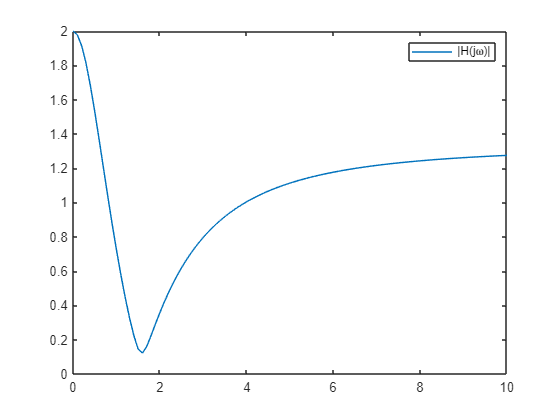

figure 
plot(w, abs(H))
legend('|H(j\omega)|')

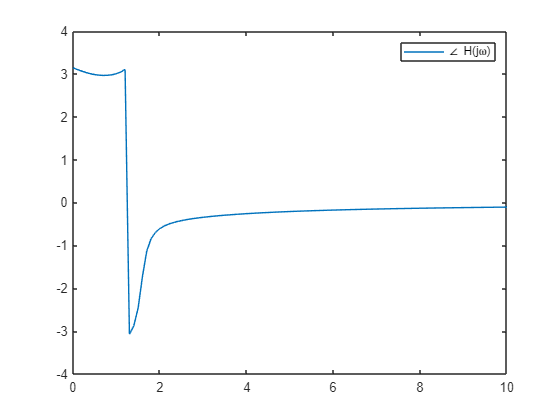

plot(w, angle(H))
legend('\angle H(j\omega)')

### **Resposta do sistema para uma entrada senoidal**

Suponha um sistema descrito por uma resosta em frequência $H\left(j\omega \right)\ldotp$ A resposta do sistema para uma entrada senoidal $x\left(t\right)=A\;\cos \left(\omega_0 \;t+\phi \;\right)$é dado por


$$y\left(t\right)=A|H\left(j\omega_0 \right)|\cos \left(\omega_0 t+\phi +\angle \;H\left(j\omega_0 \right)\right)$$


onde onde $\left|H\left(j\omega_0 \right)\right|$ é a magnitude e $e^{j\angle \;H\left(j\omega_0 \right)}$ é a fase de $H\left(j\omega \right)$ em $\omega =\omega_0$.

**Exercício 4: **Um sistema é descrito pela resposta em frequência 

$H\left(j\omega \right)=\frac{3{\left(j\omega \right)}^2 +4j\omega +2}{{\left(j\omega \right)}^2 +j\omega +3}$, 

compute e plot sobre o intervalo $0\le t\le 30$,  com passo de 0.1 s, a resposta do sistema para uma entrada $x\left(t\right)=3\cos \left(t+\frac{\pi }{3}\right)$

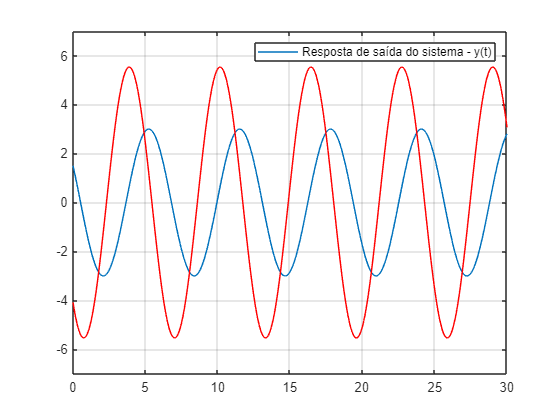

t = 0:0.1:30;
x = 3*cos(t+pi/3);
plot(t, x)
hold on
%legend('Sinal de entrada x(t)')
ylim([-4 4])
%A frequencia angular nunca é alterada, ou seja, ela é a mesma da entrada
w0 = 1;
Hw0 = (3*(j*w0)^2+4*(j*w0)+2)/((j*w0)^2+j*w0+3);
magn = abs(Hw0);
phas = angle(Hw0);
y1 = 3*magn*cos(t+ pi/3 + phas);
plot(t, y1, 'r')
legend('Resposta de saída do sistema - y(t)')
ylim([-7 7])
grid on

%Forma alternativa 
num = [3 4 2];
den = [1 1 3];
yls = lsim(num, den, x1, t)

Unrecognized function or variable 'x1'.

figure 
plot(t, yls)
legend('Resposta de saída do sistema - yls(t)')
hold off

### **Função de transferência e Resposta em Frequência**

Se um sistema é estável, a relação entre função de transferência $H\left(s\right)$e $H\left(j\omega \right)$existe de tal forma que pode ser computada substituindo $s$ por $j\omega$ em $H\left(s\right)$.

Uma forma de computar $H\left(j\omega \right)$sobre uma faixa de frequência $\omega_1 \le \omega \le \omega_2$ de uma função de transferência $H\left(s\right)$pode ser usando o comando `freqresp.`

**Exercício 5: **Compute e plot a resposta em frequência de um sistema com função transferência $H\left(s\right)=\frac{1}{s+3}$, no intervalo $-10\le \omega \le 10$ rad/s, com passo de 0.1 rad/s.

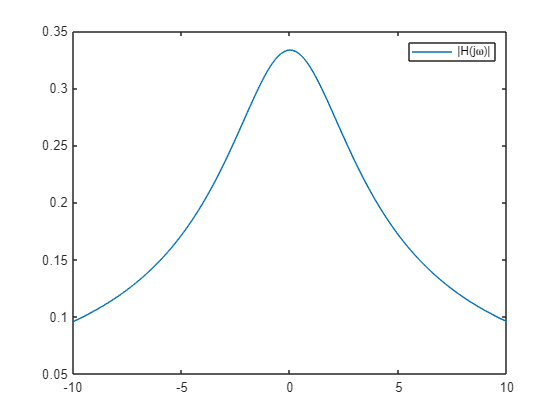

Hw = tf(1, [1 3]);
w = -10:0.1:10;
Hw = freqresp(Hw, w);
figure
plot(w, abs(Hw(:,:)))
legend('|H(j\omega)|')

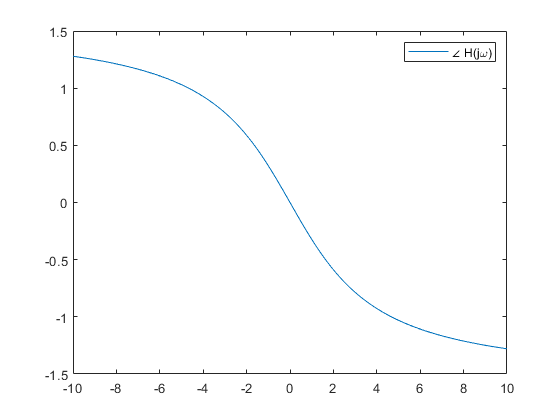

figure
plot(w, angle(Hw(:,:)))
legend('\angle H(j\omega)')

### **Diagrama de Bode**

O diagrama de Bode é uma gráfico escalonado logaritmicamente da função de transferência $H\left(s\right)$ versus a frequência $\omega$, que na realidade mostra a resposta em frequência do sistema. O diagrama é implementado com o comando `bode(Hs,w)`, onde `Hs `denota a função de transferência e `w `é o vetor contendo frequências positivas para qual $H\left(s\right)$é avaliada. 

- A sintaxe `[mag,phas] = bode(Hs,w)` retorna a magnitude e a fase de $H\left(s\right)$avaliados nos pontos de frequência especificados no vetor `w`

- Alternativamente, pode-se usar `H = freqs(num,den,w)` e então plotar a magnitude digitando `semilogx(w,20*log10(abs(H))) `e a fase `semilogx(w,rad2deg(angle(H)))`

**Exercício** **6:** Crie um diagrama de Bode do sistema com a função de transferência 


$$H\left(s\right)=\frac{s+2}{s^2 +3s+1}$$


no intervalo $0\le \omega \le 100$ rad/s, com passo de 0.1 rad/s 

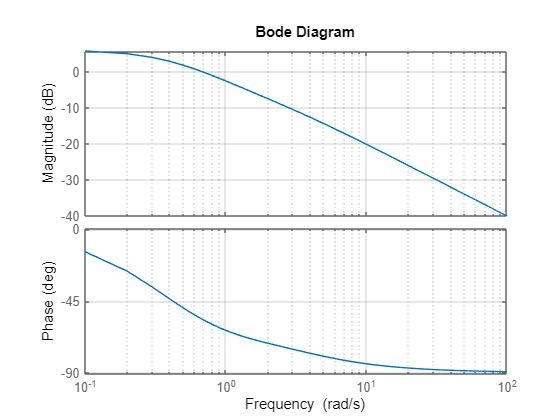

%Diagrama de Bode 
num = [1 2];
den = [1 3 1];
H = tf(num, den);
w = 0:0.1:100;
bode(H, w)
grid on